I_gray = imread('pout.tif')

I_gray = 291×240 uint8 矩阵
   107   108   107   106    99   101   102   107   107   103   112   164   200   197   170   182   213   214   212   197   137   112   110   109   112   110   107   105   106   106   107   109   108   106   106   106    99    98    99   101    99   102   103   105   103   119   147   205   204   209
   109   106   108   107   103   102   103   110   113   108   128   182   210   210   182   166   189   210   213   210   167   119   110   108   112   110   106   106   107   107   105   107   106   107   108   107   106   102    95   103   106   108   121   120   109   128   161   208   207   212
   107   106   110   110   106   107   107   120   133   133   125   151   181   189   175   151   159   204   210   212   189   137   119   107   110   110   107   108   108   107   106   106   106   105   106   108   107   105    98   103   128   150   164   137   121   133   169   208   210   215
   106   107   108   108   108   108   108   114   126   146   133   14

figure(1)

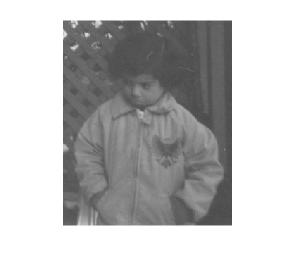

imshow(I_gray)

I_binary = imread('blobs.png')

I_binary = 272×329 logical 数组
   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   1   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   1   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

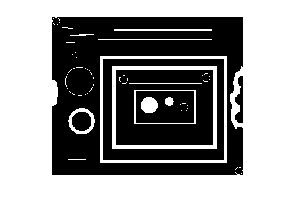

figure(2),imshow(I_binary)

% 一种压缩形式是列出所有颜色列表，图片中同一种颜色就可以用同一种编码确定，不必多占空间
% colormap列出所有用到的颜色（每种颜色都是一个RGB三元组）
% I_palette调色盘，每个像素点都填一个编号，编号会映射到colormap中的一种颜色
% 由于I_palette中每个元素都是uint8类型，最多支持0-256个编号值，因此对应的colormap为256行
% 如果colormap要存储超过256种颜色，那么I_palette中的元素就不能使用uint8类型了，需要9位才能有超过255大小的编号
% colormap中元素为double,因为使用了分母为256的归一化，这是一种对图像的处理方法，有效防止操作过程中的溢出，当数值超过1时，可以通过将大于1的值赋值为1来解决，最终存储还需要转化到uint8整型
[I_palette, colormap] = imread('trees.tif')

I_palette = 258×350 uint8 矩阵
   108   116    98   108    87    90    90    86    90    91    90    86    86    86    95   100   105   105   105   105    93   105   105   105   105   105   105   105   100    72    23    31    31    74    86    87    91   108    91   100    91    91    91    91    86    74    59    48    31    21
   112   112   112   105   112   105   112   105   105   105    93    93    93    93    93   105    93    93    93    93   105    93   105   105   105   105   105    93    77    40    34     9    41    74    91    86    91    91    91    91    87    91    91    87    74    74    50    49    49    14
   112   112   105   112   112   105   105   105   105    93    93   105    93    93    93    93    93    93    93   105   105    95    93   105   105   105   105    93    40    10     1    14    59    64    59    64    87    86    87    86    74    86    74    91    86    90    49    28    21    62
   105   105   105   105   105   112   105   105    93   105   105  

colormap =          0         0         0
    0.0627    0.0627    0.0314
    0.2902    0.0314         0
         0         0    1.0000
    0.2902    0.0627    0.0627
    0.3882    0.0314    0.0941
    0.4510    0.0627         0
    0.2588    0.1608    0.0627
    0.0941    0.2588    0.0314
    0.2235    0.1922    0.2235


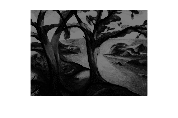

figure(4), imshow(I_palette)

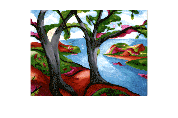

figure(5), imshow(I_palette, colormap)

whos colormap

  Name            Size            Bytes  Class     Attributes

  colormap      256x3              6144  double              



x = imread("trees.tif")

x = 258×350 uint8 矩阵
   108   116    98   108    87    90    90    86    90    91    90    86    86    86    95   100   105   105   105   105    93   105   105   105   105   105   105   105   100    72    23    31    31    74    86    87    91   108    91   100    91    91    91    91    86    74    59    48    31    21
   112   112   112   105   112   105   112   105   105   105    93    93    93    93    93   105    93    93    93    93   105    93   105   105   105   105   105    93    77    40    34     9    41    74    91    86    91    91    91    91    87    91    91    87    74    74    50    49    49    14
   112   112   105   112   112   105   105   105   105    93    93   105    93    93    93    93    93    93    93   105   105    95    93   105   105   105   105    93    40    10     1    14    59    64    59    64    87    86    87    86    74    86    74    91    86    90    49    28    21    62
   105   105   105   105   105   112   105   105    93   105   105    93   1

whos x

  Name        Size             Bytes  Class    Attributes

  x         258x350            90300  uint8              



whos colormap
whos I_palette

[I_rgb, rgb_map] = imread('peppers.png')

I_rgb = 384×512×3 uint8 数组
I_rgb(:,:,1) =

    62    63    63    65    66    63    61    63    63    64    64    61    65    64    61    62    63    65    65    64    61    64    65    64    66    71    67    65    64    62    68    68    70    70    71    70    68    74    74    70    70    71    71    72    74    70    69    70    67    67    67    69    69    66    67    67    71    70    69    67    68    71    69    70    71    71    71    70    67    68    67    60    57    56    51    46    45    51    54    54    55    58    54    54    57    58    60    60    58    59    57    60    63    67    70    69    70    70    69    71    70    67    68    69    66    67    68    66    67    64    63    65    66    66    65    62    62    66    66    64    63    64    62    65    67    61    64    64    65    65    62    61    65    68    67    65    70    70    65    66    68    68    67    70    70    72    70    70    70    68    70    71    71    71    68    71    73    71    69   


rgb_map =

     []



% 三通道提取为灰度
R = I_rgb(:,:,1)

R = 384×512 uint8 矩阵
   62   63   63   65   66   63   61   63   63   64   64   61   65   64   61   62   63   65   65   64   61   64   65   64   66   71   67   65   64   62   68   68   70   70   71   70   68   74   74   70   70   71   71   72   74   70   69   70   67   67
   63   61   59   64   63   60   61   64   64   63   63   65   65   64   63   63   63   64   62   61   65   63   62   65   66   72   71   70   66   65   70   68   68   69   68   69   67   73   74   71   69   68   70   74   73   71   72   69   63   63
   65   63   63   66   66   62   60   66   64   64   64   67   68   64   61   66   66   64   66   65   64   62   59   61   65   69   66   64   67   69   70   70   69   69   68   68   69   70   69   67   68   68   66   67   71   73   68   70   67   64
   63   67   67   63   64   62   63   68   67   67   66   64   65   68   63   65   66   67   67   64   64   64   62   67   69   72   68   67   70   69   69   68   69   67   66   68   70   68   66   65   67   70   69   68   69 

G = I_rgb(:,:,2)

G = 384×512 uint8 矩阵
   29   31   34   30   27   31   31   30   30   31   30   30   30   32   31   30   30   32   32   29   29   30   29   30   30   31   33   33   35   32   31   35   31   31   33   34   33   37   37   36   36   37   36   34   35   34   34   35   34   32
   31   31   32   30   28   31   31   32   31   31   30   30   30   30   31   32   32   33   31   32   33   32   30   33   32   32   37   36   37   34   31   33   32   32   33   35   34   34   34   37   39   36   36   37   37   34   35   35   35   31
   29   30   31   30   31   31   30   31   32   32   31   31   32   32   34   32   32   32   30   32   35   35   33   33   33   34   37   36   36   34   32   35   34   34   35   36   38   35   35   37   38   36   34   35   36   36   36   36   34   31
   29   29   31   31   31   32   33   31   32   33   32   32   32   34   35   35   32   32   30   33   35   34   32   33   32   32   34   35   36   35   36   37   36   35   34   37   38   36   36   35   35   34   33   34   38 

B = I_rgb(:,:,3)

B = 384×512 uint8 矩阵
   64   64   64   60   59   62   62   61   59   58   61   58   56   59   59   60   62   64   61   58   57   56   58   61   61   66   67   63   62   62   64   66   65   63   65   68   67   69   69   69   70   67   67   69   70   70   67   65   63   65
   62   64   64   60   59   61   62   62   63   60   62   58   56   60   63   61   62   61   60   63   62   58   60   65   65   66   66   65   67   68   69   68   67   62   60   66   68   68   67   69   71   68   68   68   68   71   72   66   64   63
   60   62   63   61   61   64   63   63   61   64   65   63   61   60   63   65   67   62   60   63   66   65   62   64   67   66   67   66   67   71   73   69   66   66   68   68   69   69   68   66   65   67   67   67   71   70   69   71   66   64
   62   63   63   60   62   62   62   62   64   65   65   66   63   63   63   68   65   63   61   63   63   62   62   66   64   66   68   66   67   68   70   69   66   65   65   67   69   69   69   67   66   67   67   69   72 

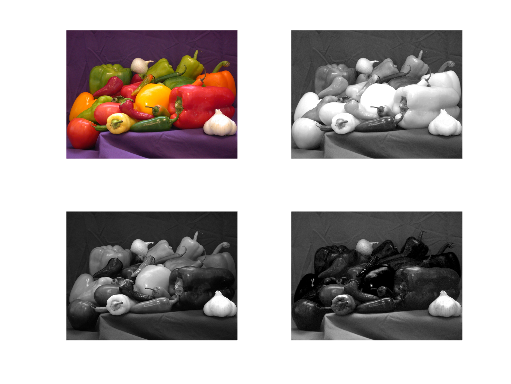

figure(1)
subplot(2,2,1), imshow(I_rgb)
subplot(2,2,2), imshow(R)
subplot(2,2,3), imshow(G)
subplot(2,2,4), imshow(B)

% 三通道提取为灰度
R = I_rgb(:,:,1)

R = 384×512 uint8 矩阵
   62   63   63   65   66   63   61   63   63   64   64   61   65   64   61   62   63   65   65   64   61   64   65   64   66   71   67   65   64   62   68   68   70   70   71   70   68   74   74   70   70   71   71   72   74   70   69   70   67   67
   63   61   59   64   63   60   61   64   64   63   63   65   65   64   63   63   63   64   62   61   65   63   62   65   66   72   71   70   66   65   70   68   68   69   68   69   67   73   74   71   69   68   70   74   73   71   72   69   63   63
   65   63   63   66   66   62   60   66   64   64   64   67   68   64   61   66   66   64   66   65   64   62   59   61   65   69   66   64   67   69   70   70   69   69   68   68   69   70   69   67   68   68   66   67   71   73   68   70   67   64
   63   67   67   63   64   62   63   68   67   67   66   64   65   68   63   65   66   67   67   64   64   64   62   67   69   72   68   67   70   69   69   68   69   67   66   68   70   68   66   65   67   70   69   68   69 

G = I_rgb(:,:,2)

G = 384×512 uint8 矩阵
   29   31   34   30   27   31   31   30   30   31   30   30   30   32   31   30   30   32   32   29   29   30   29   30   30   31   33   33   35   32   31   35   31   31   33   34   33   37   37   36   36   37   36   34   35   34   34   35   34   32
   31   31   32   30   28   31   31   32   31   31   30   30   30   30   31   32   32   33   31   32   33   32   30   33   32   32   37   36   37   34   31   33   32   32   33   35   34   34   34   37   39   36   36   37   37   34   35   35   35   31
   29   30   31   30   31   31   30   31   32   32   31   31   32   32   34   32   32   32   30   32   35   35   33   33   33   34   37   36   36   34   32   35   34   34   35   36   38   35   35   37   38   36   34   35   36   36   36   36   34   31
   29   29   31   31   31   32   33   31   32   33   32   32   32   34   35   35   32   32   30   33   35   34   32   33   32   32   34   35   36   35   36   37   36   35   34   37   38   36   36   35   35   34   33   34   38 

B = I_rgb(:,:,3)

B = 384×512 uint8 矩阵
   64   64   64   60   59   62   62   61   59   58   61   58   56   59   59   60   62   64   61   58   57   56   58   61   61   66   67   63   62   62   64   66   65   63   65   68   67   69   69   69   70   67   67   69   70   70   67   65   63   65
   62   64   64   60   59   61   62   62   63   60   62   58   56   60   63   61   62   61   60   63   62   58   60   65   65   66   66   65   67   68   69   68   67   62   60   66   68   68   67   69   71   68   68   68   68   71   72   66   64   63
   60   62   63   61   61   64   63   63   61   64   65   63   61   60   63   65   67   62   60   63   66   65   62   64   67   66   67   66   67   71   73   69   66   66   68   68   69   69   68   66   65   67   67   67   71   70   69   71   66   64
   62   63   63   60   62   62   62   62   64   65   65   66   63   63   63   68   65   63   61   63   63   62   62   66   64   66   68   66   67   68   70   69   66   65   65   67   69   69   69   67   66   67   67   69   72 

R_0 = R.*0

R_0 = 384×512 uint8 矩阵
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

G_0 = G.*0

G_0 = 384×512 uint8 矩阵
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

B_0 = B.*0

B_0 = 384×512 uint8 矩阵
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

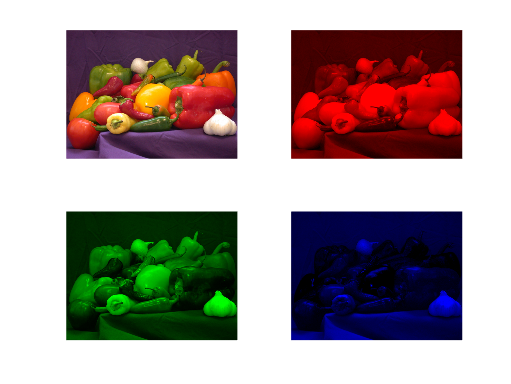

% 复制为0 R(:) = 0


figure(1)
subplot(2,2,1), imshow(I_rgb)
% cat 拼接 维度,拼接元件
subplot(2,2,2), imshow(cat(3, R, G_0, B_0))
subplot(2,2,3), imshow(cat(3, R_0, G, B_0))
subplot(2,2,4), imshow(cat(3, R_0, G_0, B))

clear

I = imread('pout.tif')

I = 291×240 uint8 矩阵
   107   108   107   106    99   101   102   107   107   103   112   164   200   197   170   182   213   214   212   197   137   112   110   109   112   110   107   105   106   106   107   109   108   106   106   106    99    98    99   101    99   102   103   105   103   119   147   205   204   209
   109   106   108   107   103   102   103   110   113   108   128   182   210   210   182   166   189   210   213   210   167   119   110   108   112   110   106   106   107   107   105   107   106   107   108   107   106   102    95   103   106   108   121   120   109   128   161   208   207   212
   107   106   110   110   106   107   107   120   133   133   125   151   181   189   175   151   159   204   210   212   189   137   119   107   110   110   107   108   108   107   106   106   106   105   106   108   107   105    98   103   128   150   164   137   121   133   169   208   210   215
   106   107   108   108   108   108   108   114   126   146   133   146   1

G = imnoise(I, 'gaussian')

G = 291×240 uint8 矩阵
   129   117   110    96   131    89    94    87   114    93   101   135   176   212   202   211   208   181   205   153   125    89    85   109    89   141    92   109   142   117   115   143   118    95    70   107   112    97    96    57   110   123    88    85   130   108    96   237   183   225
    76    83   138    99    90   110    86   139    98    82   107   192   200   178   155   161   149   245   241   164   179   131   127    86    76    96   105   111   100   158   106    89   110    98   121   116    88    69    86   127   113    55   114    85   127   151   166   195   197   163
   132   134   140   103   123    82   131   141   113    98   113   163   158   200   167   111   148   224   231   209   150   143   134   107    77   114   113    95    93    94   130   130    92   153    88   104   124   142   117   102   151   167   164   114    80   157   176   204   231   209
    98    90    83   122   105   116   110   122   167   159   143   165   1

figure(1), subplot(1,3,1), imshow(I)
subplot(1,3,2), imshow(G)
J = imnoise(I, 'salt & pepper')

J = 291×240 uint8 矩阵
   107   108   107   106    99   101   102   107   107   103   112   164   200   197   170   182   213   214   212   197   137   112   110   109   112   110   107   105   106   106   107   109   108   106   106   106    99    98    99   101    99   102   103   105   103   119   147     0   204   209
   109   106   108   107   103   102   103   110   113   108   128   182   210   210   182   166   255   210   213   210   167   119   110   108   112   110   106     0   107   107   105   107   106   107   108   107   106   102    95   103   106   108   121   120   109   128   161   208   207   212
   107   106   110   110   106   107   107   120   133   133   255   151   181   255     0   151   159   204   210   212   189   137   119   107   255   110   107   108   108   107     0   106   106   105   106     0   107   105    98   103   128   150   164   137   121   133   169   208   210   215
   106   107   108   255   108   108   255   114   126   146   133   146   1

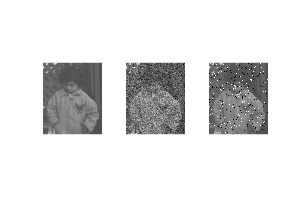

subplot(1,3,3), imshow(J);

imwrite(G, 'C:\Users\shiwenbo\Desktop\cv_matlab\gpout.tif')
imwrite(J, 'C:\Users\shiwenbo\Desktop\cv_matlab\ipout.tif')

peper_hsv = rgb2hsv(I_rgb)

peper_hsv = peper_hsv(:,:,1) =

    0.8238    0.8283    0.8278    0.8571    0.8632    0.8385    0.8280    0.8434    0.8535    0.8636    0.8480    0.8495    0.8762    0.8594    0.8444    0.8438    0.8384    0.8384    0.8535    0.8619    0.8542    0.8725    0.8657    0.8480    0.8565    0.8542    0.8333    0.8438    0.8448    0.8333    0.8514    0.8434    0.8547    0.8632    0.8596    0.8426    0.8381    0.8559    0.8559    0.8382    0.8333    0.8529    0.8524    0.8465    0.8504    0.8333    0.8429    0.8571    0.8535    0.8429    0.8382    0.8438    0.8485    0.8495    0.8490    0.8476    0.8547    0.8524    0.8529    0.8429    0.8480    0.8571    0.8529    0.8434    0.8429    0.8514    0.8571    0.8438    0.8280    0.8565    0.8468    0.8148    0.8278    0.8333    0.8229    0.8267    0.8086    0.8167    0.8506    0.8278    0.8222    0.8276    0.8194    0.8472    0.8690    0.8563    0.8444    0.8441    0.8333    0.8490    0.8393    0.8333    0.8438    0.8380    0.8288    0.8283    0.84


his = 

  Map - 属性:

        Count: 0
      KeyType: char
    ValueType: any




ans =

  空的 1×0 cell 数组



a = 1

his =   Map - 属性:

        Count: 1
      KeyType: char
    ValueType: any


flag =      1    23     4   123     4
     1    23     4     4     4


flag =      1     1    23    23     4     4   123     4     4     4


r = 2

c = 5

flag =      1     1    23    23     4     4   123     4     4     4


count =      2     5     2     1


elem =      1     4    23   123


temp =      1     2
     4     5
    23     2
   123     1


flag =      1     3     4     4


ans =      1     1
     3     1
     4     2


flag = [1,3,4,3,6;
        77,70,20,4,3]

flag =      1     3     4     3     6
    77    70    20     4     3


myHisteq(flag)

hist_map =      1     1
     3     3
     4     2
     6     1
    20     1
    70     1
    77     1


ans =      1     1
     3     3
     4     2
     6     1
    20     1
    70     1
    77     1


help imwrite

 imwrite - 将图像写入图形文件
    此 MATLAB 函数 将图像数据 A 写入 filename 指定的文件，并从扩展名推断出文件格
    式。imwrite 在当前文件夹中创建新文件。输出图像的位深取决于 A 的数据类型和文件格式。对于
    大多数格式来说：

    imwrite(A,filename)
    imwrite(A,map,filename)

    imwrite(___,fmt)

    imwrite(___,Name,Value)

    输入参数
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/imwrite.html#btv3cny-1-A">A</a> - 图像数据
            矩阵
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/imwrite.html#btv3cny-1-filename">filename</a> - 输出文件名
            字符向量 | 字符串标量
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/imwrite.html#btv3cny-1-map">map</a> - 索引图像的颜色图
            m×3 数组
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/imwrite.html#btv3cny-1-fmt">fmt</a> - 输出文件格式
            'bmp' | 'gif' | 'hdf' | 'jpg' | 'jp2'

    名称-值参数
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/imwrite.html#btv3cny-1-Background

help size

 size - 数组大小
    此 MATLAB 函数 返回一个行向量，其元素是 A 的相应维度的长度。例如，如果 A 是一个 3×4
    矩阵，则 size(A) 返回向量 [3 4]。

    sz = size(A)
    szdim = size(A,dim)
    szdim = size(A,dim1,dim2,…,dimN)
    [sz1,...,szN] = size(___)

    输入参数
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/size.html#bvfgzsm-1-A">A</a> - 输入数组
            标量 | 向量 | 矩阵 | 多维数组
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/size.html#bvfgzsm-1-dim">dim</a> - 查询的维度
            正整数标量 | 由正整数标量组成的向量
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/size.html#mw_dda7c7f5-9ad9-4379-a52f-253516c02f19">dim1,dim2,…,dimN</a> - 查询的维度列表
            正整数标量

    输出参数
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/size.html#bvfgzsm-1-sz">sz</a> - 数组大小
            由非负整数组成的行向量
        <a href="D:\Program Files\MATLAB\R2022a\help\matlab\ref/size.html#bvfgzsm-1-szdim">szdim</a> - 维度长度
            非负整数标量 | 